### 1) MATRİSLER

Matrisler iki boyutlu vektörlerdir. Ancak MATLAB'de 2'den fazla boyutta da matrisler oluşturulabilir. Bir matris aşağıda verildiği gibi tanımlanabilir.

A1 = [1 2; 3 4];
B = [-3 -7 4; 5 8 12];
C = [0 -4 9 7 16; -6 17 15 24 22; 2 -13 11 14 -21];

C_size = size(C);
C12 = C(1, 2);
C(2, 3) = 100;
C41 = C(4, 1);
C_sub = C(2 : 3, [1 3 5]);
C(4, 3) = -27; % What do you expect as the result?

İki matrisin birbirine eşit olup olmadığını kontrol etmek için normal eşitlik kontrol etme operatörü kullanılabilir. İki matrisin elemanları ayrı ayrı kontrol edilerek sonuçta yine bir matris elde edilir.

D = [1 2 3 4 5; 6 7 8 9 10];
E = [1 2 3 4 5; 7 8 9 10 11];
matrix_equality = D == E

### ÖRNEKLER

**1)** Aşağıda verilen M ve N matrislerinin birbirine eşit olup olmadığını kontol ederek sonuçta eşitlik durumunda "1", diğer durumda ise "0" elde ediniz. İpucu olarak aşağıdaki adımlar verilmiştir:

- Bir matristeki toplam eleman sayısını elde ediniz.

- Matrislerin eşitliklerini kontrol ettikten sonra kaç tane eşit eleman olduğunu sayınız.

- Eşit eleman sayısı toplam eleman sayısına eşit ise sonuç 1, değilse 0 olacaktır.

MATLAB'de tanımlı `sum` fonksiyonunun girdi olarak bir vektör aldığında çıktıya o vektörün elemanlarının toplamını döndürdüğünü öğrenmiştik. Ancak `sum` fonksiyonu girdi olarak bir matris aldığında çıktıya her bir sütunun toplamından oluşan bir satır vektör döndürür:


$$\text{sum}\bigg(A = \pmatrix{1 & 3 & 4 \cr 5 & 7 & 9}\bigg) = \pmatrix{6 & 10 & 13}$$


Bir matristeki tüm elemanları toplayabilmek için `sum` fonksiyonu aşağıdaki gibi kullanılmalıdır:

sum_val = sum(A, "all");

Bu bilgiden yola çıkarak verilen problemi yukarıdaki adımları izleyerek aşağıda çözünüz.

M = [1 3 7; 5 6 9];
N = [1 3 7; 5 6 8];

num_elements = numel(M);
num_equal_elements = sum(M == N, "all");
equality = num_elements == num_equal_elements;

Tamamen sıfırlardan veya birlerden oluşan matrisler ile birim matris aşağıda verildiği gibi oluşturulabilir.

Z23 = zeros(2, 3);
O37 = ones(3, 7);
I3 = eye(3);
I34 = eye(6, 4)

Matrislerin transpozu daha önce vektörler için anlatıldığı şekilde elde edilebilir.

F = [2 4 5; 6 8 10];
F_transpose = transpose(F);

Matrislerin aritmetik işlemleri aşağıda verildiği gibi yapılabilir.

M1 = [1 2 3; 4 5 6];
M2 = [-3 -7 8; -5 3 -11];
matrix_addition = M1 + M2;
matrix_subtraction = M1 - M2;
matrix_dot_product = M1 .* M2;
M1 = 3 * M1;

M3 = [-2 15 6 17; -1 0 4 3];
M4 = [5 7 13 16 34; -3 12 14 -16 -5; 1 -18 -26 -33 28; 9 -18 -13 36 21];
matrix_multiplication = M3 * M4;

M5 = [2 4 6; 8 10 12];
V1 = [3; 5; 7];
mat_vec_multiplication = M5 * V1;

inequality_check = (M5 > 9);

M6 = [3 5; 7 9];
M6_inv = inv(M6);
M6_inv2 = M6^(-1);

M6_square = M6.^2;
M6_square2 = M6^2;

Rastgele (random) elemanlardan oluşan vektörler ve matrisler oluşturmak için bazı hazır fonksiyonlar kullanılabilir.

uni_vec = rand(1, 7); % Uniformly distributed vector in the range [0 1]
uni_mat = rand(3, 5);
uni_int_vec = randi([1, 4], [1, 5]); % Uniformly distributed integers 
% in the vector [1 4]
uni_int_mat = randi([1, 4], [5, 4]);
gauss_vec = randn(1, 1e5); % Gaussian distributed vector with zero mean and 
% unit variance

**2)** [1 5] aralığında dengeli dağılımlı rastgele tam sayılardan oluşan bir vektörde 3 elemanının sıklığını hesaplayınız.

vec = randi([1, 5], [1, 1e5]);
freq = length(find(vec == 3)) / length(vec);

**3)** Bir madeni parayı 3 defa attığınızda en az bir yazı gelme olasılığını hesaplayan kodu yazıp teorik değerle karşılaştırınız.

num_experiment = 1e5;
E = randi([0, 1], [3, num_experiment]);
P_exp = sum(sum(E) > 0) / num_experiment;
P_theo = 7 / 8;

### 2) PROBLEM / KÜLTÜR HESABI

Kitap kurdu olan bir kişi elindeki kitapların hepsini bitirdikten sonra yeni bir kitap almaya karar vermiştir. Bunun için yeni alabileceği 10 adet kitap belirlemiştir. Ancak hesaplı bir kişi olduğu için internetten 3 farklı kitap satışı yapan sitede aynı kitapların fiyatlarını araştırmış ve sonucunda bir tablo yapmıştır. Tabloyu aşağıdaki gibi elde etmiştir:

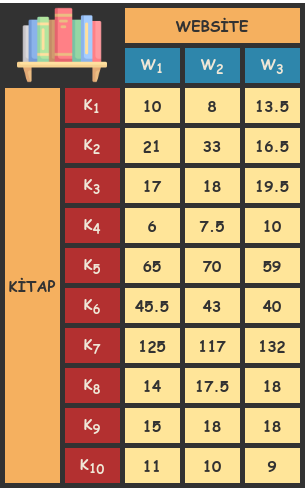

Sadece fiyatlara göre alışveriş yapmak istemeyen ve kullanıcıların memnun kalıp kalmadığını da araştıran kitap kurdumuz, kullanıcıların yukarıdaki kitap alışverişlerini yaptıklarında ne kadar memnun kaldıklarına dair bir tablo oluşturmak istemektedir.

**1)** Kullanıcı puan tablosunu biz rastgele olarak oluşturacağız. Puanlamanın 1'den 5'e kadar olduğu düşünülürse, 4 adet kullanıcının her bir websiteden aldığı her kitap için verdiği puanı içeren bir matrisi, rastgele olarak oluşturunuz.

*Hint: Burada 3 adet değişken (kullanıcılar, kitaplar ve siteler) olduğu için 3 boyutlu bir matris oluşturulmalıdır.*

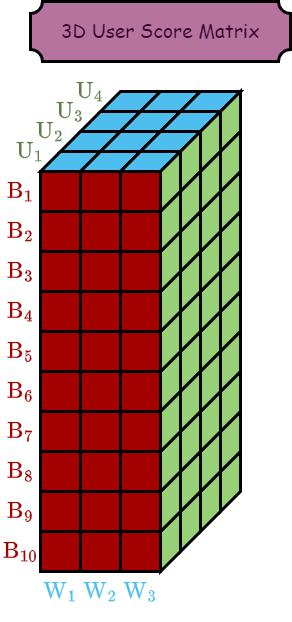

% User Score Matrix////////////////////////////////////////
user_score_matrix = randi([1, 5], [10, 3, 4]);
% /////////////////////////////////////////////////////////

**2) **Kitap kurdumuz, bu iki tabloyu (kullanıcı puan ve fiyat tabloları) kullanarak bazı istatistikler elde edip, hangi siteden hangi kitabı sipariş vereceğine karar verecektir.

- **a)** Bunun için ilk adım olarak kitapların en ucuza satıldığı websitelerden oluşan bir vektör elde edecektir.

- **b)** Sonrasında kitapların her bir websiteden satıldıklarında ortalama aldıkları puanlardan oluşan bir matris elde edecektir.

- **c)** Üçüncü adımda kitapların en ucuza satıldıkları sitelerde ortalama kaç puan aldıklarını içeren bir vektör elde edecektir.

- **d)** Üçüncü adımda elde edilen vektörde en yüksek puana denk gelen kitabı ve bu kitabın en ucuza satıldığı siteyi seçecektir.

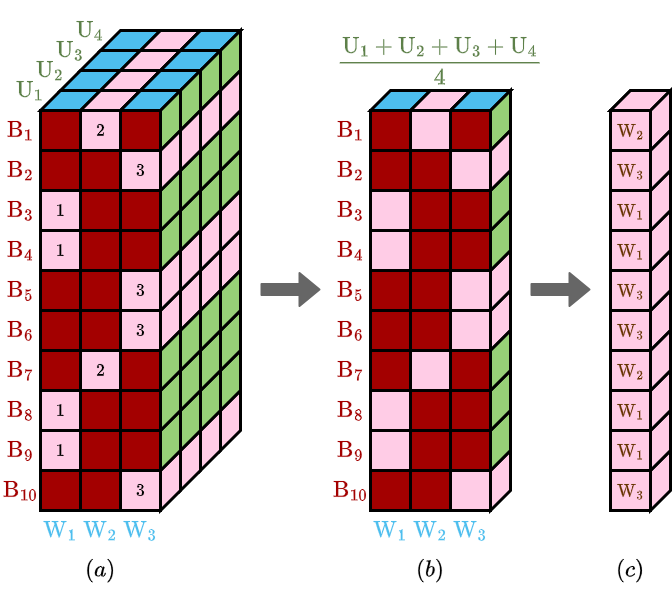

% Price Matrix/////////////////////////////////////////////
price_matrix = [10 8 13.5; 21 33 16.5; 17 18 19.5; 6 7.5 10; 65 70 59;
    45.5 43 40; 125 117 132; 14 17.5 18; 15 18 19.5; 11 10 9];
% /////////////////////////////////////////////////////////

% a) Books With Minimum Price//////////////////////////////
% TASK: Finding the indices of the websites that each
% book is sold at minimum price.
[~, min_price_ind_vec] = min(price_matrix, [], 2);
% /////////////////////////////////////////////////////////

% b) User Score Matrix with Average Scores of Users////////
% TASK: Averaging the user score matrix over the users
% to obtain the 2D average user score matrix on the
% middle.
avg_user_score_matrix = mean(user_score_matrix, 3);
% /////////////////////////////////////////////////////////

% c) Average User Score Vector of Minimum Price Websites///
% TASK: Creating the 1D average user score vector on the
% right composed of average user score values corresponding
% to minimum price websites.
S = avg_user_score_matrix(1 : 10, min_price_ind_vec);
avg_user_score_vec = diag(S);
% /////////////////////////////////////////////////////////

% d) Book and Website Selection////////////////////////////
[~, book_choice] = max(avg_user_score_vec);
website_choice = min_price_ind_vec(book_choice);
% /////////////////////////////////////////////////////////
